addpath 'Exp Data'
clc
clear all;

# Term Project Report

## Modelling

This section will deal with modelling the pendulum servo system under consideration. First, the model is presented...

### Determination of System Parameters from Experimental Data

First, the experimental data for the motor speed constant, $K_m$, the tachometer constant $K_t$, and the potentiometer constant $K_p$ is imported and the values are determined using a linear curve fit. The data is found in the "SS_speeds_voltages_data.xlsx" excel spreadsheet located in the "Exp Data" repository sub-folder. The parameters are defined as follows:


$$\begin{array}{rl}


K_m

&= ~\frac{ \omega_{ss}}{v_m}\\

K_t

&= ~\frac{v_t}{ \omega}\\

K_p

&= ~\frac{v_p}{ \theta_o}\\



\end{array}$$


Where $\omega_{ss}$ is the motor's steady state angular velocity reached when a step input voltage of $v_m$ is applied. The voltage $v_t$ is an output of the tachometer for any given, instantanous motor angular velocity $\omega$. For the position constant, the voltage $v_p$ represents the potentiometer voltage reading given gear reduced ouput angle $\theta_o$. This output angle is related to the motor shaft angle through gear ratio $N$: 

$\theta_o = \frac{\theta_m}{N}$.

#### Set up the Import Options and Import the Steady State Speed vs. Voltage Data

This portion of code was generated automatically in MATLAB using the "Import Data" tool and its "Generate Live Script" functionality. The file path for the readtable function call has been modified to work with the file system scheme used in this report. Additionally, the data originally output as an array is transfered into the struct "SS_w_v_dat". 

opts = spreadsheetImportOptions("NumVariables", 4);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A3:D13";

% Specify column names and types
opts.VariableNames = ["MotorSpeed", "Vo", "Vm", "VT"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Import the data
SSspeedsvoltagesdata = readtable("F:\Sourcetree Repos\Matlab Personal\EE 514\Term Project\Exp Data\SS_speeds_voltages_data.xlsx", opts, "UseExcel", false)

SSspeedsvoltagesdata = 11×4 table
    MotorSpeed      Vo        Vm       VT  
    __________    ______    ______    _____

          0            0    -0.025        0
        650       -0.873      4.25     -9.8
        900       -1.061      5.36    -13.5
       1450       -1.463       7.6    -21.4
       1800       -1.762      9.26    -27.1
       2200        -2.04     10.86      -33
          0        0.223     0.774        0
        245       -0.463      2.06     -3.6
        140       -0.368      1.56    -1.65
          0       -0.271      1.07        0
         60        -0.32       1.3    -1.01


Convert to output type to an array and then fill a struct with the data 

SSspeedsvoltagesdata = table2array(SSspeedsvoltagesdata);
SS_w_v_dat.MotorSpeed = SSspeedsvoltagesdata(:,1);
SS_w_v_dat.Vm = SSspeedsvoltagesdata(:,3);
SS_w_v_dat.Vt = SSspeedsvoltagesdata(:,4);

Clear temporary variables

clear opts SSspeedsvoltagesdata

#### Sort the Data By Increasing Values of Motor Speed

[MotorSpeed, I] = sort(SS_w_v_dat.MotorSpeed);
SS_w_v_dat.MotorSpeed = MotorSpeed;
SS_w_v_dat.Vm = SS_w_v_dat.Vm(I);
SS_w_v_dat.Vt = SS_w_v_dat.Vt(I);
clear MotorSpeed

#### Set up the Import Options and Import the Position Sensor Data

#### Determine the System Parameters

Deadzone voltage is determined by finding the maximum voltage associated with zero motor speed. The assumption is made that that data point coincides with the motor's first non-zero velocity. 

DZ_index = SS_w_v_dat.MotorSpeed == 0;
DZ_voltage = max(SS_w_v_dat.Vm(DZ_index)) - 0;
fprintf(['Deadzone voltage is determined to be ' num2str(round(DZ_voltage,4)) ' [volts]'])

Deadzone voltage is determined to be 1.07 [volts]

Results for Motor Parameters $v_{DZ}$ and $K_m$.

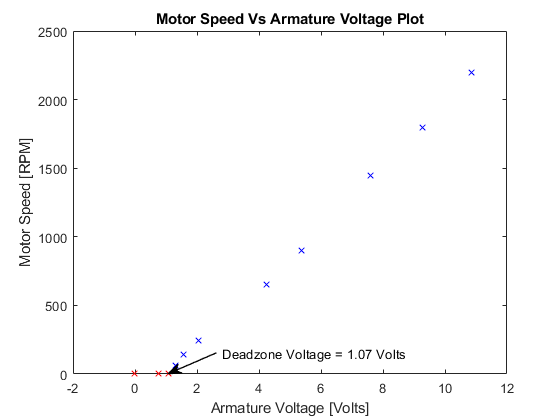


plot(SS_w_v_dat.Vm(DZ_index),SS_w_v_dat.MotorSpeed(DZ_index), 'r x',SS_w_v_dat.Vm(~DZ_index),SS_w_v_dat.MotorSpeed(~DZ_index), 'b x')
xlabel('Armature Voltage [Volts]')
ylabel('Motor Speed [RPM]')
title('Motor Speed Vs Armature Voltage Plot')

%Deadzone Location Annotation
ax = gca;
LArr = .1; %Length of Arrow
PhiArr = deg2rad(30);
%Arrow Head
[xh, yh] = ds2nfu(ax,SS_w_v_dat.Vm(length(SS_w_v_dat.Vm(DZ_index))), 0);
%Arrow Tail
xt = xh + LArr*cos(PhiArr);
yt = yh + LArr*sin(PhiArr);
annotation('textarrow',[xt xh],[yt yh],'String',['Deadzone Voltage = ' num2str(round(DZ_voltage,4)) ' Volts'],'FontSize',10,'Linewidth',1)

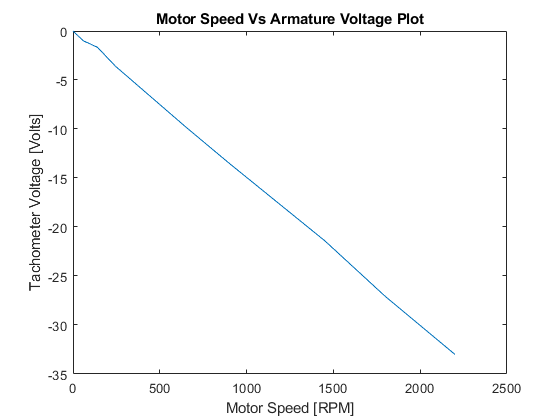


plot(SS_w_v_dat.MotorSpeed,SS_w_v_dat.Vt)
xlabel('Motor Speed [RPM]')
ylabel('Tachometer Voltage [Volts]')
title('Motor Speed Vs Armature Voltage Plot')